## EEL839 - Transmissão Digital

## Parte 3 - Ataque FGSM e treinamento adversarial

Trabalho sobre o artigo: Adversarial training based channel estimation to mitigate jamming attacks in OFDM systems

Guilherme Araujo Thomaz

Este código implementa a parte do trabalho referente ao ataque à rede neural usando FGSM e ao treinamento adversarial.

## 1 - Leitura da base de dados e formatação

H = readmatrix('..\databases\train.csv');
x_train = H(:,1:2048);
y_train = H(:,2049:end);

H = readmatrix('..\databases\test.csv');
x_test = H(:,1:2048);
y_test = H(:,2049:end);

% Canais sem ruído
y_train_orig = readmatrix('..\databases\train_original.csv');
y_test_orig = readmatrix('..\databases\test_original.csv');

x_train_ds = arrayDatastore(x_train);
y_train_ds = arrayDatastore(y_train);

ds_train = combine(x_train_ds, y_train_ds);

x_test_ds = arrayDatastore(x_test);
y_test_ds = arrayDatastore(y_test);

ds_test = combine(x_test_ds, y_test_ds);

## 2 - Configuração da rede neural

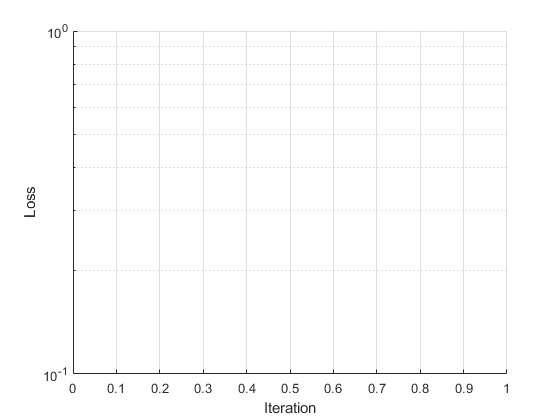

layers = [
    featureInputLayer(2048,"Normalization","none","Name","Input")
    fullyConnectedLayer(2048,"Name","Middle")
    fullyConnectedLayer(2048,"Name","End")
    ]; 
lgraph = layerGraph(layers);
net = dlnetwork(lgraph);

mini_batch_size  = 50;
num_epochs = 5; % Depois colocar 200
learn_rate = 0.001;
gradDecay = 0.75;
sqGradDecay = 0.95;
%validation_frequency = floor(numel(y_train)/mini_batch_size);
executionEnvironment = "auto";

mbq = minibatchqueue(ds_train, ...
    'MiniBatchSize',mini_batch_size,...
    'MiniBatchFormat',{'BC','BC'});

figure
lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
ylim([0 inf])
set(gca, 'YScale', 'log')
xlabel("Iteration")
ylabel("Loss")
grid on

velocity = [];
averageGrad = [];
averageSqGrad = [];

## 3 - Treinamento tradicional

iteration = 0;
start_timestamp = tic;

% Loop over epochs.
for epoch = 1:num_epochs
    
    % Shuffle data.
    shuffle(mbq)

    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration +1;

        % Read mini-batch of data.
        [dl_x,dl_y] = next(mbq);

        % Evaluate the model gradients, state, and loss.
        [gradients,state,loss] = dlfeval(@model_gradients,net,dl_x,dl_y);
        net.State = state;

        % Update the network parameters using the SGDM optimizer.
        % [net,velocity] = sgdmupdate(net,gradients,velocity,learn_rate);
        
        [net,averageGrad,averageSqGrad] = adamupdate(net,gradients,averageGrad,averageSqGrad,iteration,learn_rate,gradDecay,sqGradDecay);

        % Display the training progress.
        D = duration(0,0,toc(start_timestamp),'Format','hh:mm:ss');
        addpoints(lineLossTrain,iteration,loss)
        title("Epoch: " + epoch + ", Elapsed: " + string(D))
        drawnow
    end
end

## 4 - Teste da rede tradicional

mbq_test = minibatchqueue(ds_test, ...
    'MiniBatchSize',mini_batch_size,...
    'MiniBatchFormat',{'BC','BC'});

y_pred_train = model_predictions(net,mbq);
mse = immse(double(y_pred_train),y_train);
mse
y_pred_test = model_predictions(net,mbq_test);
mse = immse(double(y_pred_test),y_test)

## Funções auxiliares